close all
clear
clc

定义原件参数值

C = 1; L = 1/4; R1 = 1; R2 = 3/2;

定义状态空间系统

a = [-1/R1/C,-1/C;1/L,-R2/L];
b = [1/R1/C;0];
c = [-1/R1,0];
d = 1/R1;
sys = ss(a,b,c,d);

定义拨开关之前的采样时刻和激励，仿真响应，并获取终止状态

tn = [-10:0.01:-0.01]';
en = 2*(tn<0);
[rn, tn1, xn]= lsim(sys,en,tn);

x0 = xn(length(tn),:);

定义拨开关之后的采样时刻和激励，仿真零状态响应

t = [0:0.01:10]';
e = 4*(t>=0);
rzs = lsim(sys,e,t);

以前述终止状态为初始状态，以0为激励，仿真零输入响应

ezi = 0*(t>=0);
rzi = lsim(sys,ezi,t,x0);

仿真完全响应

rf = lsim(sys,e,t,x0);

分别将采样时刻和激励拼在一起，仿真完全响应

r1 = lsim(sys,[en;e],[tn;t]);

绘图

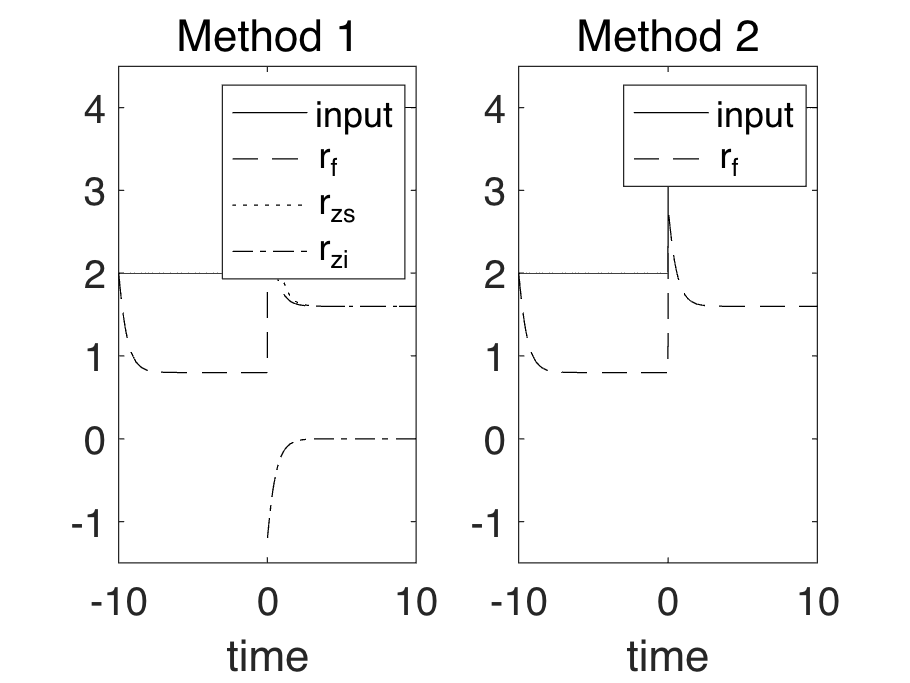

figure;
subplot(1,2,1), hold on, box on;
set(gca,'FontSize',16);
set(gca,'YLim',[-1.5,4.5]);
plot([tn;t],[en;e],'k');
plot([tn;t],[rn;rf],'k--');
plot(t,rzs,'k:');
plot(t,rzi,'k-.');
legend('input','r_f','r_{zs}','r_{zi}');
xlabel('time');
title('Method 1');

subplot(1,2,2), hold on, box on;
set(gca,'FontSize',16);
set(gca,'YLim',[-1.5,4.5]);
plot([tn;t],[en;e],'k-');
plot([tn;t],r1,'k--');
legend('input','r_f');
xlabel('time');
title('Method 2');